# Chapter 5 - Frequency Response Analysis

## Section 5 : Frequency - Response Approach to Control System Compensation

This section reviews Lead compensation, Lag compensation, and Lag-Lead compensation of control systems via Bode diagram approach. 

clear all
clc

- LEAD COMPENSATION NOTES

- Assume the Lead Compensator :  $G_c \left(s\right)=K_c \alpha \left(\frac{Ts+1}{\alpha Ts+1}\right)$ , where 0 < $\alpha$ < 1    

- Lead Angle : $\phi ={tan}^{−1} \left(\omega T\right)−{tan}^{−1} \left(\alpha \omega T\right)$

- Frequency that produces the maximum Lead Angle : $\omega_{m\text{ }} =\text{ }\frac{1}{\left(\sqrt{\alpha T}\right)}$

- Maximum Lead Angle : $sin\left(\phi_m \right)=\text{ }\frac{1−\text{ }\alpha }{1+\text{ }\alpha }$

- Using these equations and a desired gain crossover / phase crossover frequencies, determine the value for $\alpha$ and plug into $G_{c\text{ }}$

## 5-22 Determine the gain, K, of the control system such that PM = 60 deg

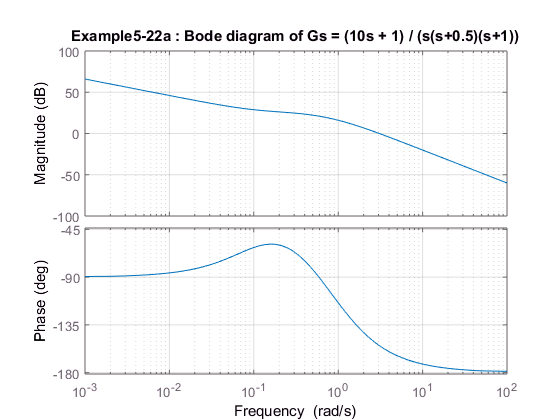

% Open Loop TF
num = [10 1];
den = [1 1.5 0.5 0];


% Plot the bode diagram of Open Loop TF when K = 1
figure
bode( num, den), grid
title('Example5-22a : Bode diagram of Gs = (10s + 1) / (s(s+0.5)(s+1))')

-     The PM = 60 deg when the frequency is 1.15 rad/ sec

-     The magnitude at w = 1.15 rad/sec is equal to -14.5 dB

-      20 * log(K) = -14.5 dB

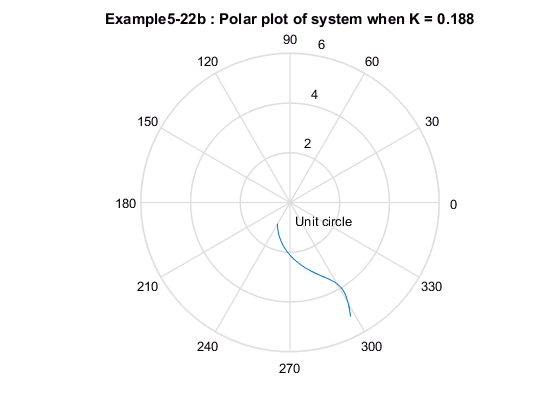

K = 0.188 

% Verify results using Nyquist Diagram 
num2 = [1.88 0.188];
den2 = [1 1.5 0.5 0];
w = 0.1: 0.01: 1.15;
[re, im, w] = nyquist(num2, den2, w);

%Define a complex vector, z, to draw Nyquist on polar plot
z = re + i*im;
r = abs(z);
th = angle(z);

% Draw polar plot

polar(th, r), grid
title( 'Example5-22b : Polar plot of system when K = 0.188')
text(0.2, -0.7, 'Unit circle')


## 5-23 Design a Lead Compensator, Gc, such that the PM = 50 deg and GM > 10 dB

clear all
clc

% Open Loop TF of the closed loop sys without compensation
num = [1] * 0.2;
den = [1 5 0 0] * 0.2;



Gs =
 
       0.2
  -------------
  0.2 s^3 + s^2
 
Continuous-time transfer function.



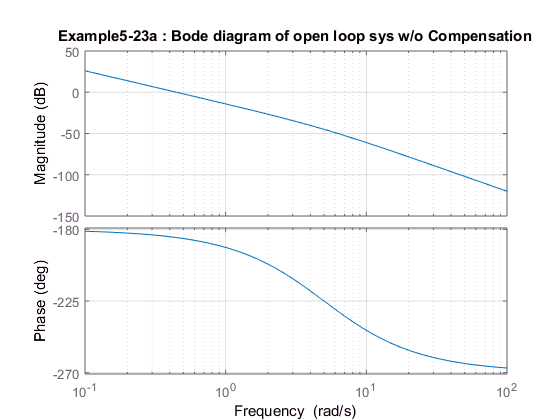

Gs = tf(num, den) 

figure
bode(num, den), grid

title('Example5-23a : Bode diagram of open loop sys w/o Compensation')

     Based on results of Bode diagram: 

-          Set the gain crossover frequency to be w = 1 rad/sec

-          At w = 1 rad/sec, the PM = 11.31 deg. Want a PM = 50 deg

-          So, Max lead angle = 50 + 11.31 = 61.31 deg of compensation at w = 1 rad/sec

% Determine alpha based on the angle compensation amount
phi_max = 61.31 * pi / 180; 
alpha = (sin(phi_max) - 1) / (-1 - sin(phi_max));

% Determine T from w_m = 1/(sqrt(alpha(T))), assuming w_m = 1
T = 1 / sqrt(alpha);

% Determine the compensator, Gc 
num2 = [T 1];
den2 = [alpha*T 1];

Gc = tf(num2, den2)


Gc =
 
   3.91 s + 1
  ------------
  0.2557 s + 1
 
Continuous-time transfer function.



% The closed loop transfer function of Gc and Gs 
Closed_loop_sys = Gc * Gs


Closed_loop_sys =
 
          0.7821 s + 0.2
  ------------------------------
  0.05115 s^4 + 0.4557 s^3 + s^2
 
Continuous-time transfer function.



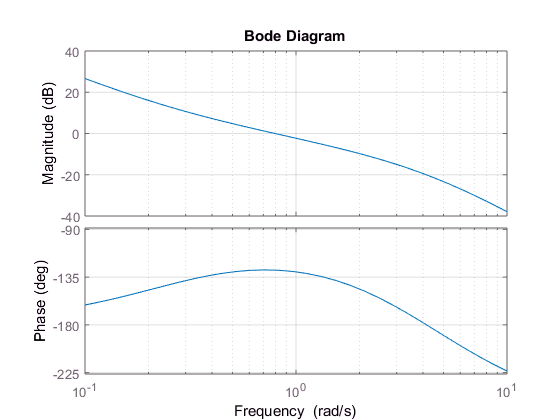


bode(Closed_loop_sys), grid
xlim([10^-1, 10^1]);


% Determine the magnitude a specific frequencies
ww = [0.5 1 2];
[mag, ph, ww] = bode(Closed_loop_sys, ww);
magdB(1) = 20 * log10(mag(:,:,1));
magdB(2) = 20 * log10(mag(:,:,2));
magdB(3) = 20 * log10(mag(:,:,3));

[ww magdB']

ans =     0.5000    4.7810
    1.0000   -2.3055
    2.0000   -9.7391


- At w = 1, the magnitude is equal to -2.3055

- Therefore, the magnitude curve must be raised by 2.3055 dB so that the magnitude curve crosses 0 dB at w = 1 rad/sec

- Therefore, the magnitude not in dB =>  20 log10(0.06541* Kc) = 2.3055

% Solve for Kc

Kc = 19.94

Kc = 19.9400

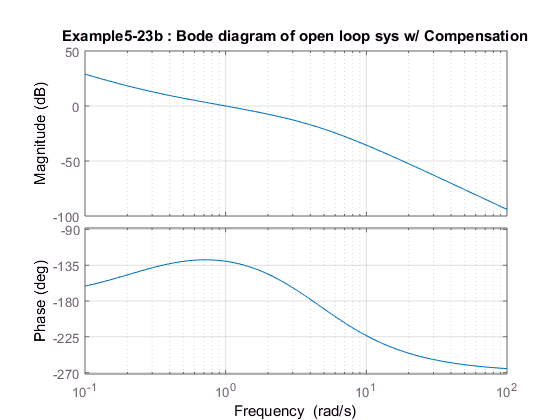


% Next, plot bode plot with Kc = 19.94
num3 = [ 1.01994 0.26086];
den3 = [0.05116 0.4558 1 0 0 ];
w = logspace(-1, 2, 100);

figure
bode(num3, den3, w), grid;
title('Example5-23b : Bode diagram of open loop sys w/ Compensation')

%Deterimine gain margin, phase margin
[Gm, Pm, wcp, wcg] = margin(num3, den3);
GmdB = 20*log10(Gm);
[GmdB Pm wcp wcg]

ans =    17.7408   49.9939    4.1535    1.0001



disp(' Gain margin = 17.74 dB')

 Gain margin = 17.74 dB


disp(' Phase margin = 49.99 deg')

 Phase margin = 49.99 deg



% Closed loop system 
sys1 = tf(num3, den3)


sys1 =
 
         1.02 s + 0.2609
  ------------------------------
  0.05116 s^4 + 0.4558 s^3 + s^2
 
Continuous-time transfer function.



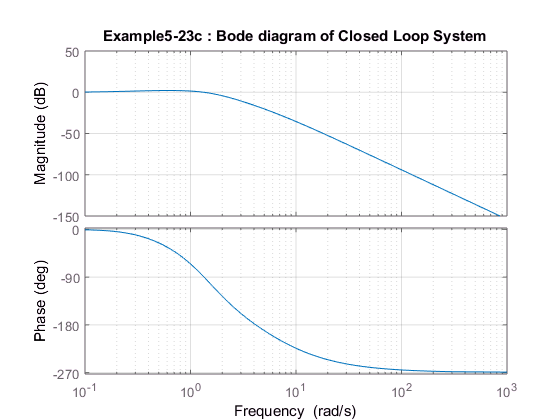

sys = feedback(sys1, [1]);

figure
bode(sys), grid
title('Example5-23c : Bode diagram of Closed Loop System')

## 5-24 Design a lead compensator such that the system has the following requirements:

 1. Static velocity error constant = 20 1/sec

 2. PM = 50 deg

 3. GM >= 10 dB. 

clear all; clc


Step # 1 : Control system G1 ( no compensator ) : $G1\left(s\right)=\text{ }\frac{10}{s\left(s+1\right)}$

- Goal: deterimine a value for K such that $K_{v\text{ }} =\text{ }\lim_{s\text{ }\longrightarrow 0} {sG}_c \left(s\right)G\left(s\right)$, the steady state performance specified to provide the required static velocity error constant : $K_{v\text{ }} =20\text{ }\frac{1}{sec}$


$$K_v =\text{ }\lim_{s\to 0} s∗\text{ }\frac{\left(Ts+1\right)}{\left(\alpha Ts+1\right)}∗\frac{10K}{s\left(s+1\right)}$$


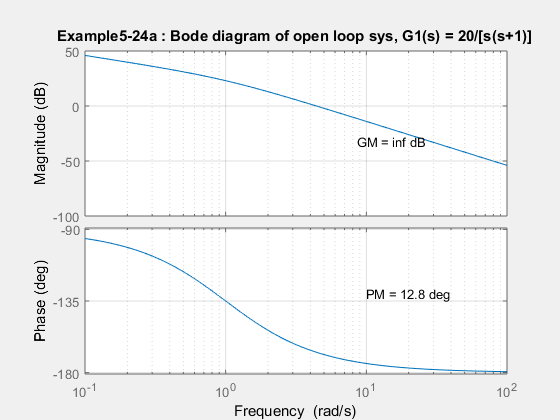

% From the previous equation: 
% The compensated system will satisfy the steady-state requirements
K = 2; 

% Plot the bode plot of system with K = 2
num = [20];
den = [1 1 0];
w = logspace(-1, 2, 100);

figure
bode(num, den, w), grid
title('Example5-24a : Bode diagram of open loop sys, G1(s) = 20/[s(s+1)]')
gtext(' PM = 12.8 deg')
gtext(' GM = inf dB')


% Determine the gain margin, phase margin, and respective frequencies
[gm, pm, wcp, wcg] = margin(num, den);
gmdB = 20*log10(gm);
disp( 'Gain margin, phase margin, and frequencies of the Open Loop system : ')

Gain margin, phase margin, and frequencies of the Open Loop system : 


[gmdB, pm, wcp, wcg]

ans =        Inf   12.7580       Inf    4.4165


Step #2 : Determine the attenuation factor based on necessary Phase Compensation

- The system requirements are PM = 50 deg

- The additional phase necessary is 37.2 deg.... can accomplish with a lead compensator

- This will shift the zero crossing of the magnitude curve to the right....to compensate for this we will need an additional 4 deg of compensation....resulting in a necessary phase of $\phi_m =41\text{ }deg$. 

- This value corresponds to an attenuation factor of $\alpha =0\ldotp 21$ based on the equation : $sin\left(\phi_m \right)=\text{ }\frac{\left(1−\text{ }\alpha \right)}{\left(1+\text{ }\alpha \right)}$

% From the equations above : 
phi_max = 41;    % deg
alpha = 0.21;    % attenuation factor


Step #3:  Determine the corner frequencies of the lead compensator

- Corner freq 1 : $\omega =\text{ }\frac{1}{T}$

- Corner freq 2: $\omega =\text{ }\frac{1}{\alpha T}$

- The maximum phase-lead angle occurs at the mean of the two corner frequencies. $\omega_c =\text{ }\frac{1}{\sqrt{\alpha }∗T}$ ....when subs into lead compensator.... $magnitude=\text{ }\frac{1}{\sqrt{\alpha }}$

- Determine frequency where magnitude equals the opposite of this on bode diagram....this becomes the new cross over frequency. 

% From equations above: 
mag_b4_compensation = -(1/sqrt(alpha));    %dB 
w_cross = 6.5;    %rad/sec

%Solve for 1/T and Kc
T_inv = w_cross * sqrt(alpha);
K_c = K / alpha;


New lead compensator design : $G_c \left(s\right)=9\ldotp 5238∗\frac{s+2\ldotp 9787}{s+14\ldotp 1842}\text{ }$

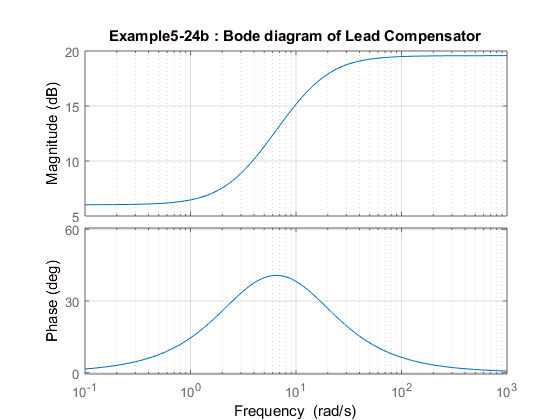

%Plot bode of compensator
numc = [9.5238 28.3685];
denc = [1 14.1842];
w = logspace(-1, 3, 100);

figure
bode(numc, denc, w), grid
title('Example5-24b : Bode diagram of Lead Compensator')

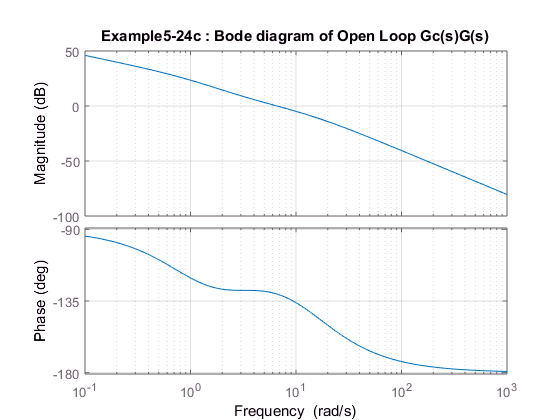


% Determine Open Loop TF of Gc(s)G(s)
numOL = [95.238 283.6854];
denOL = [1 15.1842 14.1842 0];
w = logspace(-1, 3, 100);

figure
bode(numOL, denOL, w), grid
title('Example5-24c : Bode diagram of Open Loop Gc(s)G(s)')


% Determine phase/gain margin and corresponding frequencies
[Gm2, Pm2, wcp2, wcg2] = margin(numOL, denOL);
Gm2dB = 20*log10(Gm2);
disp('The compensated gain margin and phase margins reach the requirements : ')

The compensated gain margin and phase margins reach the requirements : 


[Gm2dB, Pm2, wcp2, wcg2]

ans =        Inf   49.3687       Inf    6.6027


Step #4 : Check transient response characteristics using Unit-step Response (aka closed loop)

- Closed Loop TF of UNcompensated system : $\frac{C\left(s\right)}{R\left(s\right)}=\text{ }\frac{10}{s^2 +s+10}$

- Closed Loop TF of compensated system : $\frac{C\left(s\right)}{R\left(s\right)}=\text{ }\frac{95\ldotp 238s+283\ldotp 6854}{s^3 +15\ldotp 184s^2 +109\ldotp 4222s+283\ldotp 6854}$

- Note that closed-loop zeros and poles are at: 

                    zeros: s = -2.9787

                    poles: s = -5.227 +/-j5.7141 and s = -4.7303

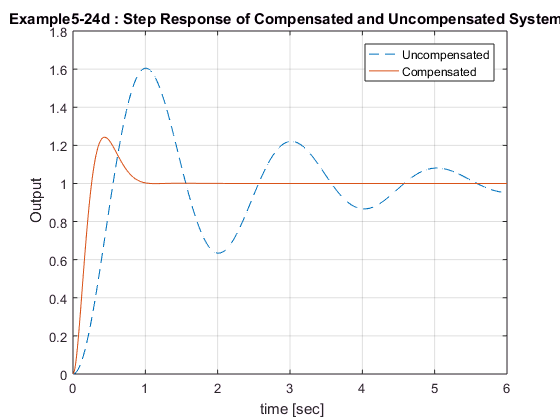

% Determine steady-state error
Kv = 20;
ess = 1 / Kv;

% plot the step responses
num1 = [10];
den1 = [1 1 10];
num2 = [95.238 283.6854];
den2 = [1 15.1842 109.4222 283.6854];
t = 0:0.01:6;

[c1, x1, t] = step(num1, den1, t);
[c2, x2, t] = step(num2, den2, t);

figure
plot(t, c1, '--', t, c2, '-'), grid
title('Example5-24d : Step Response - Compensated and Uncompensated')
xlabel(' time [sec]')
ylabel(' Output')
legend('Uncompensated', 'Compensated')

## 5-25 Lag Compensation

Problem statement: Use a lag compensator to compensate the system so that the static velocity error constant, Kv, is 5 1/secs, PM = 40 deg, and GM > 10 dB.

Open Loop TF: $G\left(s\right)=\text{ }\frac{1}{s\left(s+1\right)\left(0\ldotp 5s+1\right)}$ 

Lag Compensator: $G_c \left(s\right)=K_c \text{ }\beta \text{ }\frac{Ts+1\text{ }}{\beta Ts+1}$, where $\beta >1$ (causes phase shift...5-12 deg comp)

-     Step 1: define $K_{c\text{ }} \beta =K$ and determine $G1\left(s\right)=KG\left(s\right)$. 

-     Step 2: Adjust the gain, K, to meet static velocity error constant requirement. $K_v =5=\text{ }\lim_{s\to 0} \text{ }s\text{ }\frac{Ts+1}{\beta Ts+1}∗G1\left(s\right)=\text{ }\lim_{s\to 0} \frac{sK}{s\left(s+1\right)\left(0\ldotp 5s+1\right)}$  ----> $K=5$

-     Step 3: Determine phase margin compensation required. Current desired PM is equal to 40 +12 deg compensation --> PM = 52 deg. The frequency where the open loop phase will equal -128 deg (desired PM) is at w = 0.5 rad/sec. Set new w_cross to equal 0.5 rad/sec

-     Step 4: Determine beta --> for the magnitude to equal 0 at w_cross, the magnitude must be attenuated approx. -20 dB.  Use equation to find beta: $20log\frac{1}{\beta }=−20\text{ }dB$

-     Step 5: Plug into Lag Compensator Design: $G_c \left(s\right)=K_c \left(10\right)\frac{10s+1}{100s+1}$

-     Step 6: $K_{c\text{ }} =\text{ }\frac{K}{\beta }=0\ldotp 5$  

-     Step 7: Determine Open Loop TF : Gc(s)G(s)      $G_c \left(s\right)G\left(s\right)=\text{ }\frac{5\left(10+1\right)}{s\left(100s+1\right)\left(s+1\right)\left(0\ldotp 5s+1\right)}$

-     Step 8: Verify results using a step response analysis. Need to determine the closed loop TF of the uncomp and compensated systems. 

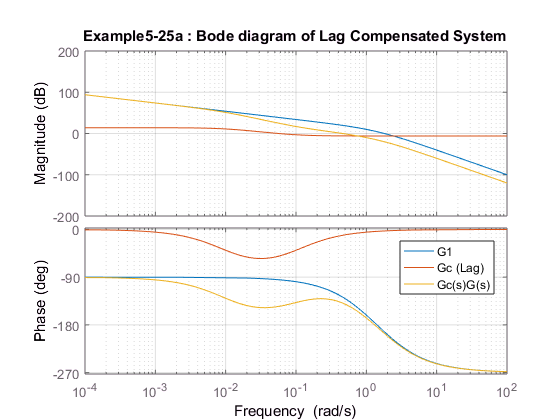

clear all; clc

% From equations above: 
K = 5;
phi_max = -128;   %  
w_cross = 0.5;    %rad/sec
beta = 10;
Kc = 0.5;

% Uncompensated system with added gain. 
num = [5];
den = [0.5 1.5 1 0];

% Lag Compensator
numc = [50 5];
denc = [100 1];

% Open Loop Compensator system 
numOL = [50 5];
denOL = [50 150 100.5 1 0];

% Plot bode diagrams
figure
bode(num, den)
hold on
bode(numc, denc)
hold on
bode(numOL, denOL),grid
legend('G1', 'Gc (Lag)', 'Gc(s)G(s)')
title('Example5-25a : Bode diagram of Lag Compensated System')
hold off 

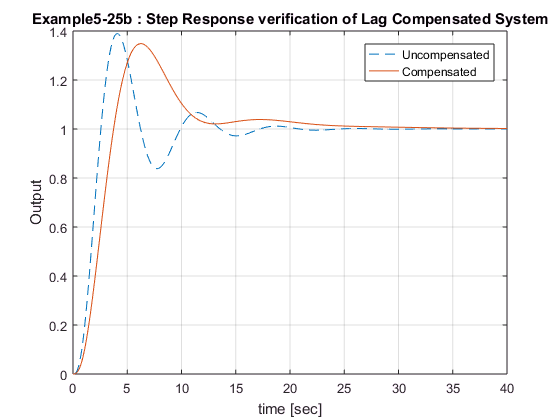


% Verify with Step Response

% Uncompensated System 
num1 = [1];
den1 = [0.5 1.5 1 1];

% Compensated System 
num2 = [50 5];
den2 = [50 150.5 101.5 51 5];

t = 0:0.1:40;
%Step response
[c1, x1, t] = step(num1, den1, t);
[c2, x2, t] = step(num2, den2, t);

%plot
figure
plot(t, c1, '--', t, c2, '-'), grid
title('Example5-25b : Step Response verification of Lag Compensated System')
xlabel('time [sec]')
ylabel('Output')
legend('Uncompensated', 'Compensated')

## 5-26 Design a compensator such that:

clear all; clc

Problem: Design a compensator that has $K_v =4\text{ }\frac{1}{sec}$, PM = 55 deg, and GM = 10 dB

Plant : $G\left(s\right)=\text{ }\frac{1}{s^2 +1}$

- Step 1: Determine K based on Kv : $K_{v\text{ }} =\text{ }\lim_{s\to 0} \text{ }s\text{ }G_c \left(s\right)∗\frac{1}{s}∗\left(\frac{1}{s^2 +1}\right)$

K = 4;

- Step 2: Determine G1(s) = KG(s)

num = [4];
den = [1 0.00000000001 1 0];
w = logspace(-2,2,100);
figure 
bode(num, den, w)
title('Example5-26a : Bode Plot of Uncompensated/ Compensated system')
hold on

Want to bring phase region @ higher frequencies up, so need to use a Lead/Lag Compensator

Select Gc(s) = (as + 1)(bs + 1) 

Use trial and error to adjust a and b in Gc so that the bode plot does what you want. 

    Set a = 5, to add +90 deg to higher frequency phase

    Set b = 0.25 to bring phase down at the magnitude crossover frequency, and present a     

    PM = 55 deg

- Step 3 : Design $G_c \left(s\right)=\left(5s+1\right)\left(0\ldotp 25s+1\right)$ 

- Step 4:  Determine open loop TF

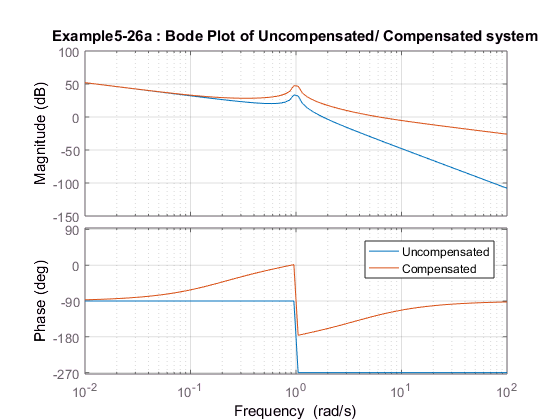

% OL TF 
numOL = [5 21 4];
denOL = [1 0 1 0];

%plot bode
bode(numOL, denOL, w)
grid
legend('Uncompensated', 'Compensated') 
hold off

- Step 5: Verify results using unit-step response

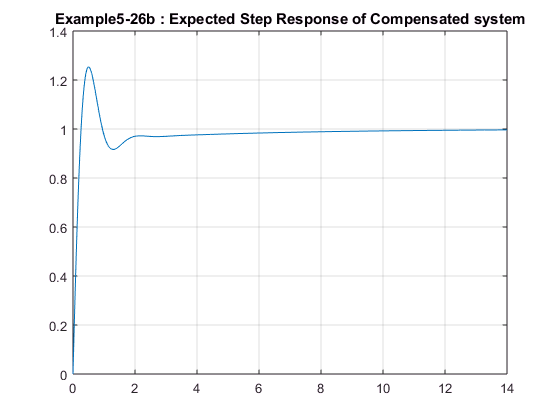

% Closed Loop TF of Compensated system 
num1 = [5 21 4];
den1 = [1 5 22 4];
t = 0:0.01:14;

c = step(num1, den1, t);
figure; 
plot(t, c), grid
title('Example5-26b : Expected Step Response of Compensated system')

## 5-27 Lead-Lag Compensation

clear; clc

Plant: $G\left(s\right)=\text{ }\frac{K}{s\left(s+1\right)\left(s+4\right)}$

Design a lead-lag compensator such that the static velocity error constant is 10 sec^-1, the PM=50 deg, and the GM > 10 dB

Lead-Lag Compensator: $G_c \left(s\right)=K_c \frac{\left(s+\text{ }\frac{1}{T_1 }\right)\left(s+\text{ }\frac{1}{T_2 }\right)}{\left(s+\frac{\beta }{T_1 }\right)\left(s+\frac{1}{\beta T_2 }\right)}$

- Step 1: Determine K from $K_v =\text{ }\lim_{s\to 0} s\text{ }G_c \left(s\right)G\left(s\right)$

K = 40; 
% G1 no compensation
num = [40];
den = [1 5 4 0];
w = logspace(-3, 2, 500);

figure
bode(num, den, w), grid
title('Example5-27a : Bode Plot of Lead/Lag Compensated system')
hold on
% Determine margins
[Gm, Pm, wcp, wcg] = margin(num, den);

GmdB = 20*log(Gm);
disp('The gain margin, phase margin, and frequencies are shown:')

The gain margin, phase margin, and frequencies are shown:


[GmdB, Pm, wcp, wcg]

ans =   -13.8629  -15.0110    2.0000    2.7797


- Step 2: Choose a new gain crossover frequency...the phase crossover frequency is at w =2 rad/sec. Because we want to adjust the phase +50 deg, set wc = 2 rad/sec

- Step 3: Determine beta and phi_max $sin\left(\phi_m \right)=\text{ }\frac{\left(\beta −1\right)}{\left(\beta +1\right)}$ --> solve for lag pole, $\omega =\text{ }\frac{1}{\beta T_2 }$ ---> w = 0.02

- Step 4: Deterimine the lag portion of the compensator --> $\frac{\left(s+0\ldotp 2\right)}{\left(s+0\ldotp 02\right)}$

w_cross = 2; %rad/sec
phase_max = 54.9; %necessary phase to reach PM
beta = 10;


- Step 5: Determine the lead portion of the compensator --> $\frac{\left(s+0\ldotp 4\right)}{\left(s+4\right)}$

% Compensator , Gc(s)
numc = [1 0.6 0.08];
denc = [1 4.02 0.08];
bode(numc, denc,w)


- Step 6: Determine open loop TF 

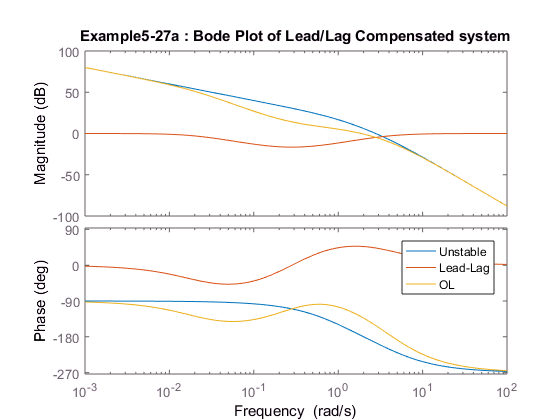

numOL = [40 24 3.2];
denOL = [1 9.02 24.18 16.48 0.32 0];
bode(numOL, denOL, w)
grid
legend('Unstable', 'Lead-Lag', 'OL')
hold off


% Determine margins
[Gm2, Pm2, wcp2, wcg2] = margin(numOL, denOL);
GmdB2 = 20*log(Gm2);
disp('The gain margin, phase margin, and frequencies are shown:')

The gain margin, phase margin, and frequencies are shown:


Result = [GmdB2, Pm2, wcp2, wcg2]

Result =    27.4444   50.6797    4.3869    1.8618
